%% Select Excel file
[file, path] = uigetfile('*.xlsx','Select Excel spreadsheet');
if isequal(file,0)
    error('No file selected');
end
filename = fullfile(path,file);


%% Read data from ArchT and Control tabs
ArchT_data = readtable(filename,'Sheet','ArchT');
Control_data = readtable(filename,'Sheet','Control');

%% Add Group variable
ArchT_data.Group = repmat("ArchT", height(ArchT_data), 1);
Control_data.Group = repmat("Control", height(Control_data), 1);

%% Combine tables
allData = [ArchT_data; Control_data];

%% Convert Subject and Group to categorical
allData.Subject = categorical(allData.Subject);
allData.Group = categorical(allData.Group);

%% Treat Day as numeric (continuous)
allData.Day = double(allData.Day);

%% Create one-vs-rest binary columns for strategy
allData.IsDirect = double(allData.Strategy == 1);
allData.IsSerial = double(allData.Strategy == 2);
allData.IsMixed  = double(allData.Strategy == 3);


%% Fit mixed-effects logistic regression for each strategy
glme_Direct = fitglme(allData,'IsDirect ~ Day*Group + (1|Subject)','Distribution','Binomial');
glme_Serial = fitglme(allData,'IsSerial ~ Day*Group + (1|Subject)','Distribution','Binomial');
glme_Mixed  = fitglme(allData,'IsMixed  ~ Day*Group + (1|Subject)','Distribution','Binomial');

%% Display results
disp('=== Direct Strategy ==='); disp(glme_Direct);

=== Direct Strategy ===

Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations             288
    Fixed effects coefficients           4
    Random effects coefficients         12
    Covariance parameters                1
    Distribution                    Binomial
    Link                            Logit 
    FitMethod                       MPL   

Formula:
    IsDirect ~ 1 + Day*Group + (1 | Subject)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    1313.2    1331.5    -651.6           1303.2  

Fixed effects coefficients (95% CIs):
    Name                         Estimate    SE         tStat      DF     pValue     Lower        Upper    
    {'(Intercept)'      }         0.6939       0.612     1.1338    284    0.25782     -0.51073       1.8985
    {'Day'              }        0.12239     0.12725    0.96185    284    0.33694    

disp('=== Serial Strategy ==='); disp(glme_Serial);

=== Serial Strategy ===

Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations             288
    Fixed effects coefficients           4
    Random effects coefficients         12
    Covariance parameters                1
    Distribution                    Binomial
    Link                            Logit 
    FitMethod                       MPL   

Formula:
    IsSerial ~ 1 + Day*Group + (1 | Subject)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    1326.2    1344.5    -658.09          1316.2  

Fixed effects coefficients (95% CIs):
    Name                         Estimate     SE         tStat      DF     pValue      Lower       Upper  
    {'(Intercept)'      }          -1.0944     0.6271    -1.7452    284    0.082039     -2.3287    0.13996
    {'Day'              }        -0.075628    0.13364    -0.5659    284     0.57191    

disp('=== Mixed Strategy ===');  disp(glme_Mixed);

=== Mixed Strategy ===

Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations             288
    Fixed effects coefficients           4
    Random effects coefficients         12
    Covariance parameters                1
    Distribution                    Binomial
    Link                            Logit 
    FitMethod                       MPL   

Formula:
    IsMixed ~ 1 + Day*Group + (1 | Subject)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    1683.6    1701.9    -836.78          1673.6  

Fixed effects coefficients (95% CIs):
    Name                         Estimate    SE         tStat       DF     pValue      Lower       Upper   
    {'(Intercept)'      }         -2.3863     1.0093     -2.3643    284    0.018739      -4.373    -0.39961
    {'Day'              }        -0.25788     0.2843    -0.90707    284     0.36514    

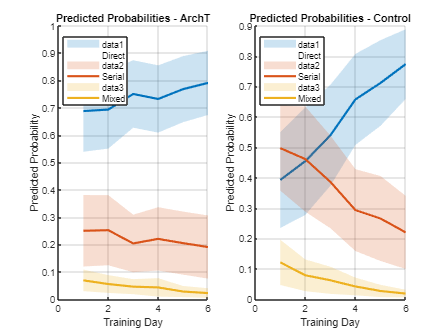

%% ====================== Predicted Probabilities with Subject Variability (Separate Subplots) ======================
days = min(allData.Day):max(allData.Day);  % range of training days
groups = {'ArchT','Control'};
strategies = {'Direct','Serial','Mixed'};
colors = lines(numel(strategies));

nSim = 100;  % number of simulations for random effects

% Store models in a cell array for easy loop
glmeModels = {glme_Direct, glme_Serial, glme_Mixed};

% Initialize results structure to hold one table per strategy
resultsStruct = struct();

figure;

for g = 1:numel(groups)
    groupName = groups{g};
    
    % Initialize arrays for mean + std of probabilities
    meanPred = zeros(numel(days), numel(strategies));
    stdPred  = zeros(numel(days), numel(strategies));
    
    for d = 1:numel(days)
        % Prepare table for this day and group
        predTable = table();
        predTable.Day = repmat(days(d), nSim,1);
        predTable.Group = repmat(categorical({groupName}), nSim,1);
        
        % Simulate subject-level random effects
        subjectIDs = randsample(unique(allData.Subject), nSim, true);
        predTable.Subject = subjectIDs;
        
        % Predict probabilities for each strategy model
        for s = 1:numel(strategies)
            [yPred, ~, ~] = predict(glmeModels{s}, predTable, 'Conditional', true);
            
            % Compute summary stats
            meanPred(d,s) = mean(yPred);
            stdPred(d,s)  = std(yPred);
            semPred = stdPred(d,s) / sqrt(nSim);
            
            % Append to the corresponding strategy table
            newRow = table(days(d), string(groupName), meanPred(d,s), stdPred(d,s), semPred, nSim, ...
                           'VariableNames', {'Day','Group','Mean','SD','SEM','N'});
            
            strategyName = strategies{s};
            if ~isfield(resultsStruct, strategyName)
                resultsStruct.(strategyName) = newRow;
            else
                resultsStruct.(strategyName) = [resultsStruct.(strategyName); newRow];
            end
        end
    end
    
    % Plot for each group (still plotting SD here)
    subplot(1, numel(groups), g); hold on;
    
    for s = 1:numel(strategies)
        fill([days fliplr(days)], ...
             [meanPred(:,s)'+stdPred(:,s)' fliplr(meanPred(:,s)'-stdPred(:,s)')], ...
             colors(s,:), 'FaceAlpha',0.2, 'EdgeColor','none');
         
        plot(days, meanPred(:,s), 'Color', colors(s,:), 'LineWidth', 2, ...
             'DisplayName', strategies{s});
    end
    
    xlabel('Training Day');
    ylabel('Predicted Probability');
    title(['Predicted Probabilities - ' groupName]);
    legend('Location','best');
    grid on;
end


%% ====================== Create Workspace Variables ======================
PredictedProbabilities_Direct = resultsStruct.Direct;
PredictedProbabilities_Serial = resultsStruct.Serial;
PredictedProbabilities_Mixed  = resultsStruct.Mixed;

disp('✅ Created workspace variables (with Mean, SD, SEM, N):');

✅ Created workspace variables (with Mean, SD, SEM, N):


disp({'PredictedProbabilities_Direct', ...
      'PredictedProbabilities_Serial', ...
      'PredictedProbabilities_Mixed'});

    {'PredictedProbabilities_Direct'}    {'PredictedProbabilities_Serial'}    {'PredictedProbabilities_Mixed'}



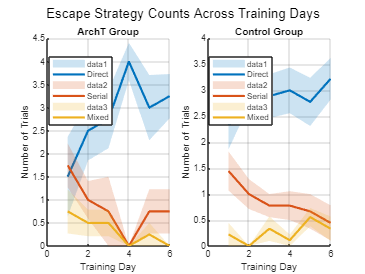

%% ====================== Line plot of number of trials by strategy (separate groups) ======================
strategies = [1 2 3];
strategyNames = {'Direct','Serial','Mixed'};
groups = {'ArchT','Control'};
colors = lines(numel(strategies));

% Structure to store data tables for each strategy
trialResults = struct();

figure;

for g = 1:numel(groups)
    groupName = groups{g};
    
    % Select group data
    if strcmp(groupName,'ArchT')
        groupData = ArchT_data;
    else
        groupData = Control_data;
    end
    
    % Create subplot for each group
    subplot(1,2,g); hold on;
    
    % Get unique days
    days = unique(groupData.Day);
    
    % Initialize mean, SD, SEM arrays
    meanCounts = zeros(numel(days), numel(strategies));
    stdCounts  = zeros(numel(days), numel(strategies));
    semCounts  = zeros(numel(days), numel(strategies));
    nCounts    = zeros(numel(days), 1);
    
    for d = 1:numel(days)
        dayData = groupData(groupData.Day == days(d), :);
        subjects = unique(dayData.Subject);
        nCounts(d) = numel(subjects);
        
        % Count number of trials of each strategy per subject
        counts = zeros(numel(subjects), numel(strategies));
        for s = 1:numel(subjects)
            subjData = dayData(dayData.Subject == subjects(s), :);
            for st = 1:numel(strategies)
                counts(s,st) = sum(subjData.Strategy == strategies(st));
            end
        end
        
        % Compute mean, SD, and SEM across subjects
        meanCounts(d,:) = mean(counts,1);
        stdCounts(d,:)  = std(counts,0,1);
        semCounts(d,:)  = stdCounts(d,:) ./ sqrt(size(counts,1));
        
        % Append results for each strategy
        for st = 1:numel(strategies)
            newRow = table(days(d), string(groupName), meanCounts(d,st), ...
                           stdCounts(d,st), semCounts(d,st), nCounts(d), ...
                           'VariableNames', {'Day','Group','Mean','SD','SEM','N'});
            
            strategyName = strategyNames{st};
            if ~isfield(trialResults, strategyName)
                trialResults.(strategyName) = newRow;
            else
                trialResults.(strategyName) = [trialResults.(strategyName); newRow];
            end
        end
    end
    
    % Plot each strategy as a line with shaded SEM
    for st = 1:numel(strategies)
        fill([days' flip(days')], ...
             [meanCounts(:,st)+semCounts(:,st); flip(meanCounts(:,st)-semCounts(:,st))], ...
             colors(st,:), 'FaceAlpha',0.2, 'EdgeColor','none'); % SEM shading
        
        plot(days, meanCounts(:,st), 'Color', colors(st,:), 'LineWidth',2, ...
            'DisplayName',strategyNames{st});
    end
    
    xlabel('Training Day');
    ylabel('Number of Trials');
    title([groupName ' Group']);
    legend('Location','best');
    grid on;
end

sgtitle('Escape Strategy Counts Across Training Days');


%% ====================== Create Workspace Variables ======================
TrialCounts_Direct = trialResults.Direct;
TrialCounts_Serial = trialResults.Serial;
TrialCounts_Mixed  = trialResults.Mixed;

disp('✅ Created workspace variables (with Mean, SD, SEM, N):');

✅ Created workspace variables (with Mean, SD, SEM, N):


disp({'TrialCounts_Direct', 'TrialCounts_Serial', 'TrialCounts_Mixed'});

    {'TrialCounts_Direct'}    {'TrialCounts_Serial'}    {'TrialCounts_Mixed'}

